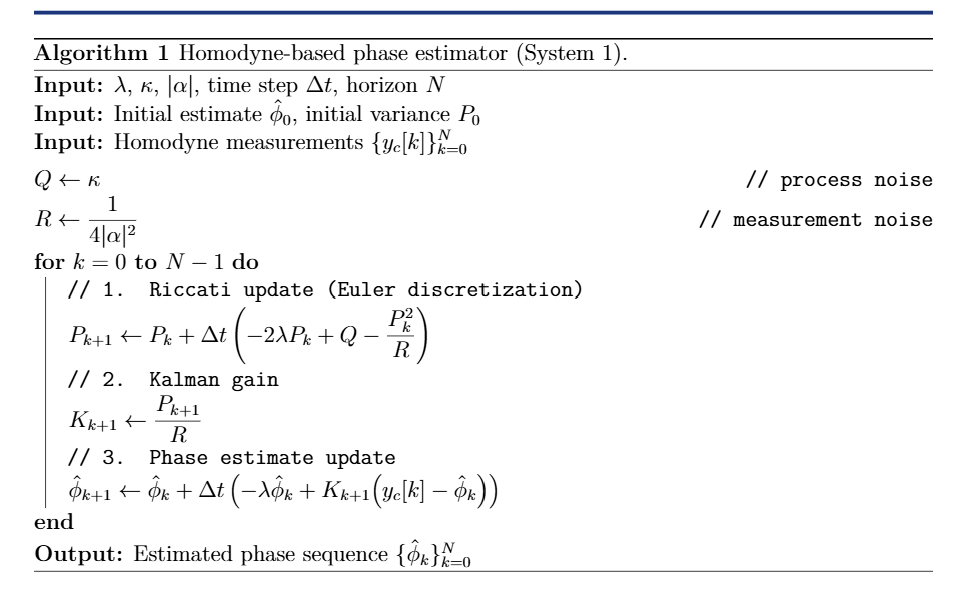

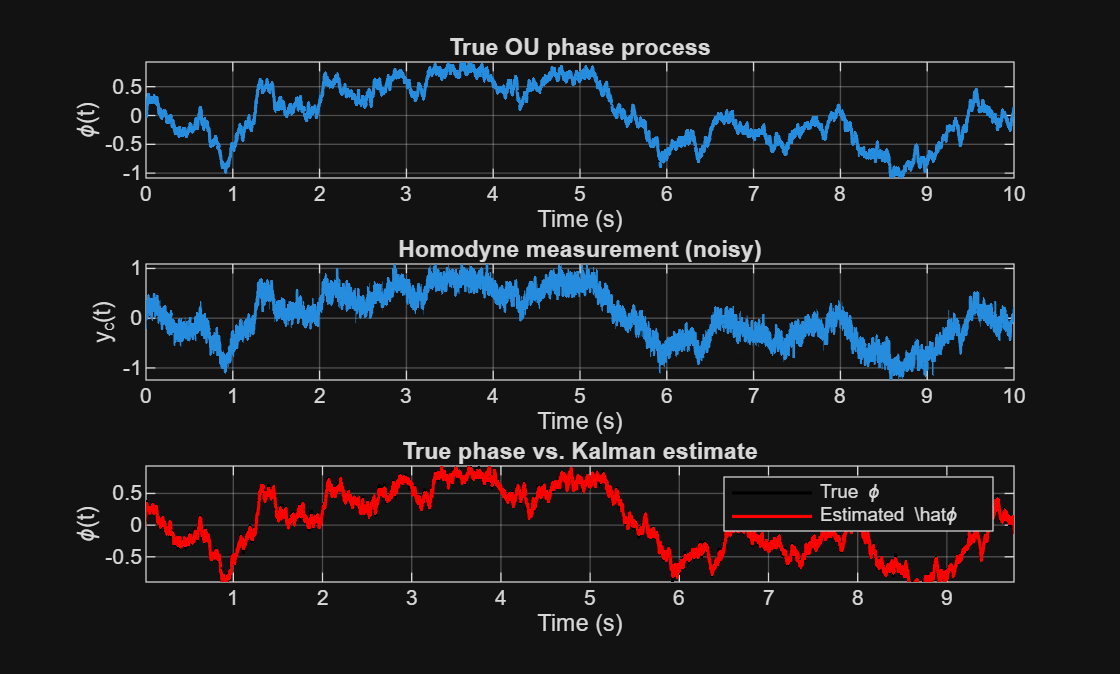

clear; clc; close all;


lambda  = 1.0;       % relaxation rate of OU process (s^-1)
kappa   = 0.5;       % phase diffusion strength
alpha   = 5.0;       % local oscillator amplitude |alpha|
T       = 10.0;      % total simulation time (s)
dt      = 1e-3;      % time step (s)

A = - lambda;
B = [sqrt(kappa) 0];
C = 1;
D = [0 1/(2*alpha)];


t  = 0:dt:T;
N  = numel(t);

% Discrete-time OU parameters (exact discretization)
a  = exp(-lambda*dt);                         % state transition coefficient
Qd = (kappa/(2*lambda))*(1 - exp(-2*lambda*dt));  % discrete process noise var

% Measurement noise (homodyne)
r  = 1/(2*abs(alpha));  % measurement noise std in y_k = phi_k + r*w_k
R  = r^2;               % measurement noise variance

%% 2. Simulate true OU phase process phi_k

phi_true = zeros(1,N);
phi_true(1) = 0;   % initial phase (can be non-zero if you want)

for k = 2:N
    eta_k = sqrt(Qd) * randn;            % process noise
    phi_true(k) = a * phi_true(k-1) + eta_k;
end

%% 3. Simulate homodyne measurements y_k

y_meas = phi_true + r*randn(1,N);        % y_k = phi_k + r*w_k

%% 4. Discrete-time Kalman filter for phase estimation

phi_hat = zeros(1,N);   % estimated phase
P       = zeros(1,N);   % estimation error variance

% Initialisation
phi_hat(1) = 0;         % prior guess
P(1)       = 1;         % initial variance (large uncertainty)

for k = 2:N
    % --- Prediction step ---
    phi_pred = a * phi_hat(k-1);
    P_pred   = a^2 * P(k-1) + Qd;
    
    % --- Update step ---
    Kk       = P_pred / (P_pred + R);              % Kalman gain
    phi_hat(k) = phi_pred + Kk * (y_meas(k) - phi_pred);
    P(k)       = (1 - Kk) * P_pred;
end

%% 5. Plots

figure;
subplot(3,1,1);
plot(t, phi_true, 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('\phi(t)');
title('True OU phase process');
grid on;

subplot(3,1,2);
plot(t, y_meas, 'LineWidth', 1.0);
xlabel('Time (s)');
ylabel('y_c(t)');
title('Homodyne measurement (noisy)');
grid on;

subplot(3,1,3);
plot(t, phi_true, 'k', 'LineWidth', 1.2); hold on;
plot(t, phi_hat, 'r', 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('\phi(t)');
title('True phase vs. Kalman estimate');
legend('True \phi', 'Estimated \hat{\phi}');
grid on;

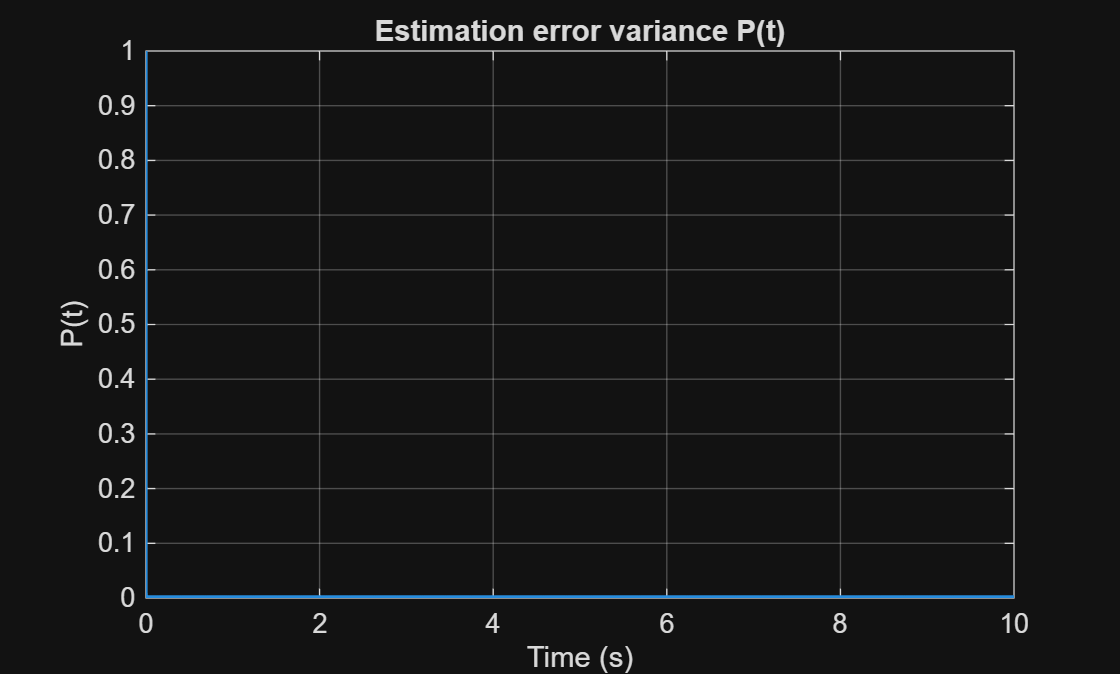


figure;
plot(t, P, 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('P(t)');
title('Estimation error variance P(t)');
grid on;